## **Workshop 2: Aircraft Navigation using GNSS and Kalman Filtering**

The aim of this workshop is to apply Kalman filtering to GNSS navigation using Matlab. An unmanned air vehicle (UAV) is flying over the Amazon jungle in Brazil, conducting an aerial survey to detect unauthorised logging. GNSS pseudo-range and pseudo-range rate measurements are logged every second. Your task is to compute a continuous GNSS navigation solution using Kalman filtering.

% Import constants
run('Define_Constants.m')

### **Task 0: Theoretical Design Problem**

A Kalman filter estimates six states using a local-tangent-plane coordinate system. These are north position, east position, north velocity, east velocity, north acceleration, and east acceleration.

#### a) Determine the exact transition matrix as a function of the state propagation interval, $\tau _s$.

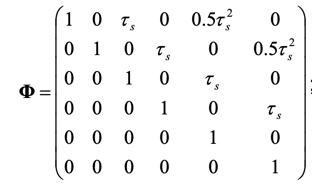

#### b) Use this to determine the position error that arises from ignoring the acceleration if the propagation interval is 0.5s and the horizontal acceleration is 4 m $s^{-2}$ north.

Note that notation in the code below excludes epoch.  

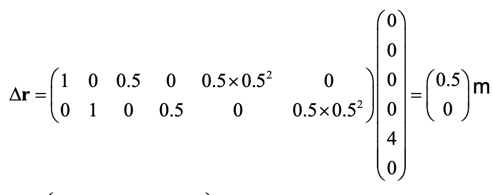

% Initialize the interval between epochs
tau_s = 0.5; % Seconds 

% Setup transition matrix
Phi = eye(6);
indices = sub2ind(size(Phi), 1:4, 3:6); % Index manipulation
Phi(indices) = tau_s;
indices = sub2ind(size(Phi), 1:2, 5:6); % Index manipulation
Phi(indices) = 0.5 * tau_s^2

Phi =     1.0000         0    0.5000         0    0.1250         0
         0    1.0000         0    0.5000         0    0.1250
         0         0    1.0000         0    0.5000         0
         0         0         0    1.0000         0    0.5000
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000



% Initialize state vector
x = [0; 0; 0; 0; 4; 0]

x =      0
     0
     0
     0
     4
     0



% Calculate position error - note that this refers to first two results (m)
delta_r = Phi * x

delta_r =     0.5000
         0
    2.0000
         0
    4.0000
         0


#### c) If the measurement vector comprises north position, east position, north velocity and east velocity, what is the measurement matrix?

% Setup measurement matrix
H_k = eye(4);
zeros_columns = zeros(4, 2);
H_k = [H_k zeros_columns]

H_k =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0


### Task 1: Basic Kalman Filter 

For task 1, you will take the simple 2-state position and velocity Kalman filter from Lecture 4 and extend it to three dimensions. The measurements input to the Kalman filter will comprise the least-squares GNSS position solution at each epoch.

For task 1, you will implement a 6-state Kalman filter estimating Cartesian ECEF position (m) and velocity (m/s).The state vector is thus: 

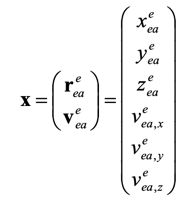

### Task 1A: Basic Kalman Filter First Epoch

For task 1A, compute the position and velocity at time 0 using the first set of measurements in Workshop2_GNSS_Pos_ECEF.csv by following the steps below.

#### 1A.a)

Initialise the Kalman filter state vector estimate using an estimated position of (2447019, -5884199, -284783) m and an estimated velocity of (184, 77, 0) m/s. Initialise the error covariance to give initial state uncertainties of 10m for each component of position and 5 m/s for each component of velocity. Thus,

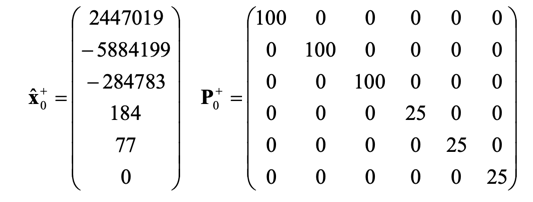

Lecture 2B p. 16

% Given state vector and uncertainties
x_0_est = [2447019; -5884199; -284783; 184; 77; 0];
sigma_p = 10; %m
sigma_v = 5; %m/s

%Setup state estimation error covariance matrix 
P_0_est = eye(6);
indices = sub2ind(size(P_0_est), 1:3, 1:3);
P_0_est(indices) = sigma_p^2;
indices = sub2ind(size(P_0_est), 4:6, 4:6);
P_0_est(indices) = sigma_v^2

P_0_est =    100     0     0     0     0     0
     0   100     0     0     0     0
     0     0   100     0     0     0
     0     0     0    25     0     0
     0     0     0     0    25     0
     0     0     0     0     0    25


#### 1A.b) 

(Kalman filter Step 1) Compute the transition matrix using

where the propagation interval, $\tau_s$, is 1s in this case.

tau_s = 1; %s

I_3 = eye(3);
zero_3 = zeros(3,3);

Phi_k_min_1 = [I_3, tau_s * I_3; zero_3, I_3]

Phi_k_min_1 =      1     0     0     1     0     0
     0     1     0     0     1     0
     0     0     1     0     0     1
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


#### 1A.c) 

(Step 2) Compute the system noise covariance matrix using

where the acceleration power spectral density (PSD) $S_a^e =5m^2 s^{-3}$

.

S_a_e = 5 %m^2 s^-3

S_a_e = 5


Q_k_min_1 = [1/3 * S_a_e * tau_s^3 * I_3, 1/2 * S_a_e * tau_s^2 * I_3; 1/2 * S_a_e * tau_s^2 * I_3, S_a_e * tau_s * I_3];

#### 1A.d)

(Step 3) Use the transition matrix to propagate the state estimates:

x_k_pred = Phi_k_min_1 * x_0_est

x_k_pred =      2447203
    -5884122
     -284783
         184
          77
           0


#### 1A.e)

(Step 4) Then use this to propagate the error covariance matrix:

P_k_pred = Phi_k_min_1 * P_0_est * Phi_k_min_1' + Q_k_min_1

P_k_pred =   126.6667         0         0   27.5000         0         0
         0  126.6667         0         0   27.5000         0
         0         0  126.6667         0         0   27.5000
   27.5000         0         0   30.0000         0         0
         0   27.5000         0         0   30.0000         0
         0         0   27.5000         0         0   30.0000


#### 1A.f)

(Step 5) Formulate the measurement matrix:

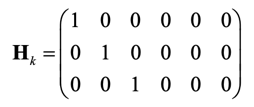

H_k = [I_3, zero_3] % Note overwriting H_k from section 0

H_k =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


#### 1A.g)

 (Step 6) Compute the measurement noise covariance matrix assuming each component of the position measurement has an error standard deviation of $\sigma_x$ = 2.5m Thus,

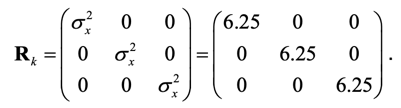

sigma_x = 2.5; %m
R_k = I_3 * sigma_x^2

R_k =     6.2500         0         0
         0    6.2500         0
         0         0    6.2500


#### 1A.h)

(Step 7) Compute the Kalman gain matrix using

K_k = P_k_pred * H_k' * inv(H_k * P_k_pred * H_k' + R_k)

K_k =     0.9530         0         0
         0    0.9530         0
         0         0    0.9530
    0.2069         0         0
         0    0.2069         0
         0         0    0.2069


#### 1A.i)

(Step 8) Formulate the measurement innovation vector $\partial\textbf{z}^-_k$ using

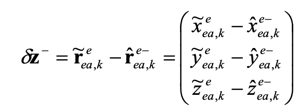

where $\tilde{\textbf{r}}^e_{ea,k}$ is the GNSS least-squares position solution and $\tilde{\textbf{r}}^{e-}_{ea,k}$is the position predicted by the Kalman filter, i.e. the first 3 components of the propagated state vector $\hat{\textbf{x}}^-_k$

r_ea_k_e_meas = readmatrix("Workshop2_GNSS_Pos_ECEF.csv", "Range", "B1:D1")';
r_ea_k_e_pred = x_k_pred(1:3); 

partial_z_pred_k = r_ea_k_e_meas - r_ea_k_e_pred

partial_z_pred_k =     1.0380
   -0.0930
   -0.3375


#### 1A.j) 

(Step 9) Update the state estimates using

x_k_est = x_k_pred + K_k * partial_z_pred_k

x_k_est = 1.0e+06 *

    2.4472
   -5.8841
   -0.2848
    0.0002
    0.0001
   -0.0000


#### 1A.k) 

(Step 10) Update the error covariance matrix using

I = eye(6)

I =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



P_k_est = (I - K_k * H_k) * P_k_pred

P_k_est =     5.9561         0         0    1.2931         0         0
         0    5.9561         0         0    1.2931         0
         0         0    5.9561         0         0    1.2931
    1.2931         0         0   24.3103         0         0
         0    1.2931         0         0   24.3103         0
         0         0    1.2931         0         0   24.3103


#### 1A.l)

Convert this Cartesian ECEF position solution to latitude, longitude and height using the Matlab function pv_ECEF_to_NED.m (supplied on Moodle). Note that the Matlab function outputs latitude and longitude in radians. Use the same Matlab function to convert the velocity solution from ECEF resolving axes to north, east and down.

% % Corrections - there is an error somewhere above
% x_k_est(6) = -0.07
% P_k_est(6, 3) = 1.293103448275865

% Isolate position solution and velocity solution
r_ea_e = x_k_est(1:3)

r_ea_e = 1.0e+06 *

    2.4472
   -5.8841
   -0.2848


v_ea_e = x_k_est(4:6)

v_ea_e =   184.2148
   76.9808
   -0.0698



% Use pre-provided formula
[L_b,lambda_b,h_b,v_eb_n] = pv_ECEF_to_NED(r_ea_e,v_ea_e)

L_b = -0.0450

lambda_b = -1.1767

h_b = 996.8093

v_eb_n =    -0.0849
  199.6522
    0.3344



% Convert to radians
L_b = rad_to_deg * L_b

L_b = -2.5759

lambda_b = rad_to_deg * lambda_b

lambda_b = -67.4176

### Task 1B: Basic Kalman Filter Multiple Epochs

Now use the same method to compute the filtered position and velocity at all of the epochs in Workshop2_GNSS_Pos_ECEF.csv. Remember that $\hat{\textbf{x}}^+_{k-1}$ and $\textbf{P}^+_{k-1}$for the current epoch are the same as for $\hat{\textbf{x}}^+_{k}$ and $\textbf{P}^+_{k}$ for the previous epoch.  

% Import data
GNSS_Pos_ECEF_data = readmatrix("Workshop2_GNSS_Pos_ECEF.csv");
num_epochs = length(GNSS_Pos_ECEF_data(:, 1));

% Initialize Kalman filter state vector before loop

% Given state vector and uncertainties
x_k_minus_1_est = [2447019; -5884199; -284783; 184; 77; 0];
sigma_p = 10; %m
sigma_v = 5; %m/s

%Setup state estimation error covariance matrix 
P_k_minus_1_est = eye(6);
indices = sub2ind(size(P_k_minus_1_est), 1:3, 1:3);
P_k_minus_1_est(indices) = sigma_p^2;
indices = sub2ind(size(P_k_minus_1_est), 4:6, 4:6);
P_k_minus_1_est(indices) = sigma_v^2;

% Step 1: Compute the transition matrix (doesn't change across epochs)
tau_s = 1; %s

I_3 = eye(3);
zero_3 = zeros(3,3);

Phi_k_minus_1 = [I_3, tau_s * I_3; zero_3, I_3];

% Step 2: Compute the system noise covariance matrix (doesn't change across epochs)
S_a_e = 5 %m^2 s^-3

S_a_e = 5


Q_k_minus_1 = [1/3 * S_a_e * tau_s^3 * I_3, 1/2 * S_a_e * tau_s^2 * I_3; 1/2 * S_a_e * tau_s^2 * I_3, S_a_e * tau_s * I_3];

% Step 5: Formulate the measurement matrix 
% (Doesn't change across epochs in standard Kalman filter)
H_k = [I_3, zero_3]; 

% Step 6: Compute the measurement noise covariance matrix
% Assumed constant across epochs
sigma_x = 2.5; %m
R_k = I_3 * sigma_x^2;

% Initialize I for step 10 
I = eye(6);

% Initialize matrix for solutions
x_solutions_final = zeros(num_epochs, 6);

for i = 1:num_epochs % For each epoch

    % Step 3: Use the transition matrix to propogate the state estimates
    x_k_pred = Phi_k_minus_1 * x_k_minus_1_est;

    % Step 4: Use this to propogate the error covariance matrix
    P_k_pred = Phi_k_minus_1 * P_k_minus_1_est * Phi_k_minus_1' + Q_k_minus_1;

    % Step 7: Compute the Kalman gain matrix
    K_k = P_k_pred * H_k' * inv(H_k * P_k_pred * H_k' + R_k);

    % Step 8: Formulate the measurement innovation vector
    r_ea_k_e_meas = GNSS_Pos_ECEF_data(i, 2:4)';
    r_ea_k_e_pred = x_k_pred(1:3); 

    partial_z_pred_k = r_ea_k_e_meas - r_ea_k_e_pred;

    % Step 9: Update the state estimates
    x_k_est = x_k_pred + K_k * partial_z_pred_k;

    % Step 10: Update the error covariance matrix
    P_k_est = (I - K_k * H_k) * P_k_pred;

    % Convert position to latitude, longitude and height
    % Isolate position solution and velocity solution
    r_ea_e = x_k_est(1:3);
    v_ea_e = x_k_est(4:6);
    
    % Use pre-provided formula
    [L_b, lambda_b, h_b, v_eb_n] = pv_ECEF_to_NED(r_ea_e,v_ea_e);
    
    % Convert to radians
    L_b = rad_to_deg * L_b;
    lambda_b = rad_to_deg * lambda_b;

    % Save results in final matrix
    x_solutions_final(i, :) = [L_b, lambda_b, h_b, v_eb_n'];

    % Update state estimates and error covariance matrix for the next loop
    x_k_minus_1_est = x_k_est;
    P_k_minus_1_est = P_k_est;


    end


### Task 1C: Basic Kalman Filter State Uncertainties (OPTIONAL)

By taking the square roots of the 1st and 4th diagonal elements of the error covariance matrix, +k P , examine how the uncertainty of the x-direction position and velocity states vary over time. Note that they converge to constant values after a few seconds. Repeat this exercise with the measurement update (steps 5 to 10) disabled and observe how the uncertainties increase over time in the absence of new measurement information.

### Task 2: GNSS Kalman Filter

We now move on to a proper GNSS Kalman filter that determines the position and velocity directly from the pseudo-range and pseudo-range rate measurements. 

For task 2 you need to extend the Kalman filter from task 1 to 8 states by adding clock offset (m) and clock drift (m/s). The state vector is thus

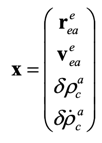

### Task 2A: GNSS Kalman Filter First Epoch

For task 2A, compute the position and velocity at time 0 using the first set of measurements in Workshop2_Pseudo_ranges.csv and Workshop2_Pseudo_range_rates.csv by following the steps below.

#### 2A.a)

Initialise the Kalman filter state vector estimate and error covariance matrix using the Matlab function Initialise_GNSS_KF.m (supplied on Moodle). Note that the initial state uncertainties are 10m for position and clock offset and 0.1 m/s for velocity and clock drift.

[x_k_minus_1_est, P_k_minus_1_est] = Initialise_GNSS_KF

x_k_minus_1_est = 1.0e+06 *

    2.4470
   -5.8842
   -0.2848
    0.0002
    0.0001
   -0.0000
    0.0099
    0.0001


P_k_minus_1_est =   100.0000         0         0         0         0         0         0         0
         0  100.0000         0         0         0         0         0         0
         0         0  100.0000         0         0         0         0         0
         0         0         0    0.0100         0         0         0         0
         0         0         0         0    0.0100         0         0         0
         0         0         0         0         0    0.0100         0         0
         0         0         0         0         0         0  100.0000         0
         0         0         0         0         0         0         0    0.0100


#### 2A.b)

(Kalman filter Step 1) Compute the transition matrix using

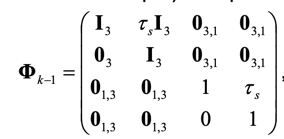

where the propagation interval, $\tau_s$, is 1s in this case.

tau_s = 1

tau_s = 1

% I_3 and zero_3 already defined
zero_3_1 = zeros(3, 1)

zero_3_1 =      0
     0
     0


zero_1_3 = zeros(1, 3)

zero_1_3 =      0     0     0



Phi_k_minus_1 = [I_3, tau_s* I_3, zero_3_1, zero_3_1; ...
    zero_3, I_3, zero_3_1, zero_3_1; ...
    zero_1_3, zero_1_3, 1, tau_s; ...
    zero_1_3, zero_1_3, 0, 1]

Phi_k_minus_1 =      1     0     0     1     0     0     0     0
     0     1     0     0     1     0     0     0
     0     0     1     0     0     1     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     1
     0     0     0     0     0     0     0     1


### 2A.c)

(Step 2) Compute the system noise covariance matrix using

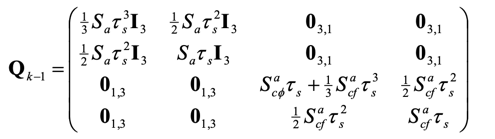

where the acceleration power spectral density (PSD), $S_a^e$, is 5$m^2 s^{-3}$, the clock phase PSD,$S^a_{c\phi}$ , is 0.01 $m^2 s^{-3}$ and the clock frequency PSD, $S^a_{cf}$, is 0.04 $m^2 s^{-1}$.

% Define constants
S_a_e = 5 %m^2 s^-3

S_a_e = 5

S_c_phi_a = 0.01 %m^2 s^-3

S_c_phi_a = 0.0100

S_cf_a = 0.04 %m^2 s^-1

S_cf_a = 0.0400



Q_k_minus_1 = [1/3 * S_a_e * tau_s^3 * I_3, 1/2 * S_a_e * tau_s^2 * I_3, zero_3_1, zero_3_1; ...
    1/2 * S_a_e * tau_s^2 * I_3, S_a_e * tau_s * I_3, zero_3_1, zero_3_1; ...
    zero_1_3, zero_1_3, S_c_phi_a * tau_s + 1/3 * S_cf_a * tau_s^3, 1/2 * S_cf_a * tau_s^2; ...
    zero_1_3, zero_1_3, 1/2 * S_cf_a * tau_s^2, S_cf_a * tau_s]

Q_k_minus_1 =     1.6667         0         0    2.5000         0         0         0         0
         0    1.6667         0         0    2.5000         0         0         0
         0         0    1.6667         0         0    2.5000         0         0
    2.5000         0         0    5.0000         0         0         0         0
         0    2.5000         0         0    5.0000         0         0         0
         0         0    2.5000         0         0    5.0000         0         0
         0         0         0         0         0         0    0.0233    0.0200
         0         0         0         0         0         0    0.0200    0.0400


#### 2A.d)

(Step 3) Use the transition matrix to propagate the state estimates:

x_k_pred = Phi_k_minus_1 * x_k_minus_1_est

x_k_pred = 1.0e+06 *

    2.4472
   -5.8841
   -0.2848
    0.0002
    0.0001
   -0.0000
    0.0100
    0.0001


#### 2A.e)

(Step 4) Then use this to propagate the error covariance matrix:

P_k_pred = Phi_k_minus_1 * P_k_minus_1_est * Phi_k_minus_1' + Q_k_minus_1

P_k_pred =   101.6767         0         0    2.5100         0         0         0         0
         0  101.6767         0         0    2.5100         0         0         0
         0         0  101.6767         0         0    2.5100         0         0
    2.5100         0         0    5.0100         0         0         0         0
         0    2.5100         0         0    5.0100         0         0         0
         0         0    2.5100         0         0    5.0100         0         0
         0         0         0         0         0         0  100.0333    0.0300
         0         0         0         0         0         0    0.0300    0.0500


#### 2A.f-h)

Predict the ranges from the approximate user position to each satellite using

where $\hat{\textbf{r}^e_{ej}$ is the Cartesian ECEF position of satellite $j$, $\hat{\textbf{r}^e_{ea}$  is the predicted Cartesian ECEF user position and $C_e^I$ is the Sagnac effect compensation matrix, given by

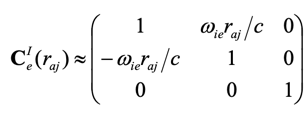

where the Earth rotation rate, $\omega_{ie$, is  $7\ldotp 292115\times {\textrm{10}}^{-5\;} \;{\textrm{rad}\;s}^{-1}$ and the speed of light, $c$, is $299792458\;m\;s^{-1}$. The recursion is resolved by initially computing the range with the Sagnac effect compensation matrix set to the identity matrix, then using this range to compute the Sagnac effect compensation matrix and then recomputing the range.

Compute the Cartesian ECEF positions of the satellites at time 0 using the Matlab function Satellite_position_and_velocity.m (supplied on Moodle). Note that this function needs the satellite numbers given in the first row of the pseudo-ranges file. Then, Compute the line-of-sight unit vector from the approximate user position to each satellite using

Predict the range rates from the approximate user position to each satellite using

where $\hat{\textbf{v}}^e_{ej}$ is the Cartesian ECEF velocity of satellite *j*, $\hat{\textbf{v}}^{e-}_{ea}$ is the predicted Cartesian ECEF user velocity and $\Omega^e_{ie}$ is the skew symmetric matrix of the Earth rotation rate vector. It is calculated for you in Define_constants.m.

% Isolate predictions
r_ea_e = x_k_pred(1:3)

r_ea_e = 1.0e+06 *

    2.4472
   -5.8841
   -0.2848


v_ea_e = x_k_pred(4:6)

v_ea_e =   184.5000
   76.9000
   -0.1000



% Get satellite positions

% Get satellite numbers from csv file
satellite_numbers = readmatrix("Workshop2_Pseudo_ranges.csv", "Range", "1:1");

% Remove the first element (not a satellite)
satellite_numbers = satellite_numbers(2:end);

% Create nx3 (n satellites) matrix for position and velocity
r_ej_e = zeros(3, length(satellite_numbers));
v_ej_e = zeros(3, length(satellite_numbers));

% For each satellite, calculate the Cartesian ECEF and store in matrix
for i = 1:length(satellite_numbers)
    satellite_number = satellite_numbers(i)
    
   [sat_r_ej_e, sat_v_ej_e] = Satellite_position_and_velocity(0, satellite_number);
    
   r_ej_e(:, i) = sat_r_ej_e; %Row to column of sat_r_es_e 
   v_ej_e(:, i) = sat_v_ej_e; %Row to column of sat_r_es_e 

end

satellite_number = 4

satellite_number = 5

satellite_number = 9

satellite_number = 14

satellite_number = 15

satellite_number = 19

satellite_number = 20

satellite_number = 24

satellite_number = 29

satellite_number = 30


% Initialize array to store distance between sat and user
r_aj_magnitude = zeros(1, length(satellite_numbers));
r_dot_aj = zeros(1, length(satellite_numbers));

% Initialize matrix to store line of sight unit vectors
u_aj_e = zeros(3, length(satellite_numbers));

for i = 1:length(satellite_numbers)
    C_e_I = eye(3);

    r_aj_magnitude(i) = norm(C_e_I * r_ej_e(:, i) - r_ea_e);

    C_e_I(1, 2) = omega_ie * r_aj_magnitude(i) / c;
    C_e_I(2, 1) = -omega_ie * r_aj_magnitude(i) / c;

    r_aj_magnitude(i) = norm(C_e_I * r_ej_e(:, i) - r_ea_e);
    u_aj_e(:, i) = (C_e_I * r_ej_e(:, i) - r_ea_e) / r_aj_magnitude(i)

    % Calculate velocity
    r_dot_aj(i) = u_aj_e(:, i)' * (C_e_I * (v_ej_e(:, i) + Omega_ie * r_ej_e(:, i)) - (v_ea_e + Omega_ie * r_ea_e))

end

u_aj_e =    -0.2440         0         0         0         0         0         0         0         0         0
   -0.7721         0         0         0         0         0         0         0         0         0
    0.5868         0         0         0         0         0         0         0         0         0


r_dot_aj =   367.1113         0         0         0         0         0         0         0         0         0


u_aj_e =    -0.2440    0.6930         0         0         0         0         0         0         0         0
   -0.7721   -0.1641         0         0         0         0         0         0         0         0
    0.5868    0.7020         0         0         0         0         0         0         0         0


r_dot_aj =   367.1113  470.8664         0         0         0         0         0         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138         0         0         0         0         0         0         0
   -0.7721   -0.1641   -0.3893         0         0         0         0         0         0         0
    0.5868    0.7020    0.9210         0         0         0         0         0         0         0


r_dot_aj =   367.1113  470.8664 -251.6082         0         0         0         0         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072         0         0         0         0         0         0
   -0.7721   -0.1641   -0.3893   -0.8746         0         0         0         0         0         0
    0.5868    0.7020    0.9210    0.4383         0         0         0         0         0         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961         0         0         0         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736         0         0         0         0         0
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124         0         0         0         0         0
    0.5868    0.7020    0.9210    0.4383    0.1989         0         0         0         0         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001         0         0         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736   -0.2477         0         0         0         0
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124   -0.7837         0         0         0         0
    0.5868    0.7020    0.9210    0.4383    0.1989   -0.5696         0         0         0         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001  305.8921         0         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736   -0.2477    0.7049         0         0         0
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124   -0.7837   -0.1669         0         0         0
    0.5868    0.7020    0.9210    0.4383    0.1989   -0.5696   -0.6893         0         0         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001  305.8921  426.3407         0         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736   -0.2477    0.7049    0.0141         0         0
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124   -0.7837   -0.1669   -0.3981         0         0
    0.5868    0.7020    0.9210    0.4383    0.1989   -0.5696   -0.6893   -0.9172         0         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001  305.8921  426.3407 -249.3370         0         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736   -0.2477    0.7049    0.0141    0.2097         0
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124   -0.7837   -0.1669   -0.3981   -0.8850         0
    0.5868    0.7020    0.9210    0.4383    0.1989   -0.5696   -0.6893   -0.9172   -0.4158         0


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001  305.8921  426.3407 -249.3370 -264.9513         0


u_aj_e =    -0.2440    0.6930    0.0138    0.2072    0.9736   -0.2477    0.7049    0.0141    0.2097    0.9779
   -0.7721   -0.1641   -0.3893   -0.8746    0.1124   -0.7837   -0.1669   -0.3981   -0.8850    0.1129
    0.5868    0.7020    0.9210    0.4383    0.1989   -0.5696   -0.6893   -0.9172   -0.4158   -0.1761


r_dot_aj =   367.1113  470.8664 -251.6082 -340.9961 -215.1001  305.8921  426.3407 -249.3370 -264.9513 -142.6341


#### 2A.i)

(Step 5) Compute the measurement matrix using

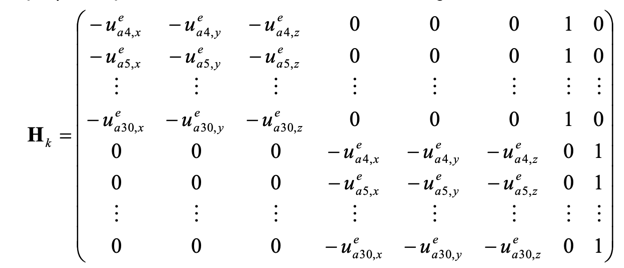

H_k = zeros(2*length(satellite_numbers), 8)

H_k =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0




for i = 1:length(satellite_numbers)
    H_k(i, 1:3) = -u_aj_e(:, i)
    H_k(i + length(satellite_numbers), 4:6) = -u_aj_e(:, i)

end

H_k =     0.2440    0.7721   -0.5868         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
   -0.2097    0.8850    0.4158         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
   -0.2097    0.8850    0.4158         0         0         0         0         0
         0         0         0         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
   -0.2097    0.8850    0.4158         0         0         0         0         0
   -0.9779   -0.1129    0.1761         0         0         0         0         0


H_k = 20×8
    0.2440    0.7721   -0.5868         0         0         0         0         0
   -0.6930    0.1641   -0.7020         0         0         0         0         0
   -0.0138    0.3893   -0.9210         0         0         0         0         0
   -0.2072    0.8746   -0.4383         0         0         0         0         0
   -0.9736   -0.1124   -0.1989         0         0         0         0         0
    0.2477    0.7837    0.5696         0         0         0         0         0
   -0.7049    0.1669    0.6893         0         0         0         0         0
   -0.0141    0.3981    0.9172         0         0         0         0         0
   -0.2097    0.8850    0.4158         0         0         0         0         0
   -0.9779   -0.1129    0.1761         0         0         0         0         0



H_k(1:length(satellite_numbers), 7) = ones(length(satellite_numbers), 1);
H_k(length(satellite_numbers)+1:end, 8) = ones(length(satellite_numbers), 1);


#### 2A.j)

(Step 6) Compute the measurement noise covariance matrix assuming all pseudo-range measurements have an error standard deviation of 10m and all pseudo-range rate measurements have an error standard deviation of 0.05 m/s. Thus,

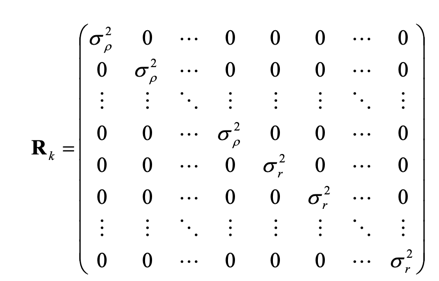

sigma_ro = 10 %m

sigma_ro = 10

sigma_r = 0.05 %m/s

sigma_r = 0.0500



R_k = diag([sigma_ro^2 * ones(1, 10), sigma_r^2 * ones(1, 10)]);

#### 2A.k)

(Step 7) Compute the Kalman gain matrix using

K_k = P_k_pred * H_k' * inv(H_k * P_k_pred * H_k' + R_k)

K_k = 8×20
    0.1417   -0.1157    0.1139   -0.0614   -0.1733    0.1417   -0.1200    0.1134   -0.0639   -0.1747    0.1064   -0.0319    0.2207   -0.2413   -0.0035    0.1056   -0.0349    0.2227   -0.2463   -0.0040
    0.0843   -0.0279   -0.0525    0.2252   -0.1091    0.0872   -0.0266   -0.0514    0.2293   -0.1092   -0.0911    0.0122   -0.2615    0.3256   -0.0481   -0.0898    0.0150   -0.2641    0.3318   -0.0477
   -0.1221   -0.1460   -0.1919   -0.0914   -0.0399    0.1209    0.1465    0.1945    0.0881    0.0389   -0.0155   -0.0194   -0.0237   -0.0141   -0.0049    0.0167    0.0194    0.0276    0.0097    0.0055
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.3419   -0.1813    0.5298   -0.5219   -0.1862    0.3404   -0.1913    0.5328   -0.5339   -0.1887
   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0823   -0.0011   -0.5435    0.8484   -0.1976   -0.0769    0.0056   -0.5472    0

#### 2A.l)

(Step 8) Formulate the measurement innovation vector $\partial\textbf{z}^-_k$ using

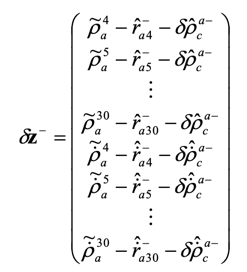

where $\tilde{\rho}_a^j$ is the measured pseudo-range from satellite *j* to the user antenna, $\tilde{\dot\rho}_a^j$ is the measured pseudo-range rate from satellite j to the user antenna, $\partial\hat{\rho}^{a-}_c$ is the propagated receiver clock offset estimate, and $\partial\hat\dot{\rho}^{a-}_c$ is the propagated receiver clock drift estimate.

% Get psuedo ranges from satellites to users in this epoch
rho_meas_data = readmatrix("Workshop2_Pseudo_ranges.csv");
rho_meas_epoch1 = rho_meas_data(2, 2:end)'

rho_meas_epoch1 = 10×1
1.0e+07 *

    2.2291
    2.3450
    2.3814
    2.0852
    2.4183
    2.1961
    2.3054
    2.3291
    2.0608
    2.4077



rho_dot_meas_data = readmatrix("Workshop2_Pseudo_range_rates.csv");
rho_dot_meas_epoch1 = rho_dot_meas_data(2, 2:end)'

rho_dot_meas_epoch1 = 10×1
  467.0631
  570.6358
 -151.7405
 -241.1198
 -115.2240
  405.9032
  526.3007
 -149.3039
 -165.0090
  -42.7388



partial_rho_c_a_pred = x_k_pred(7)

partial_rho_c_a_pred = 10001

partial_rho_dot_c_a_pred = x_k_pred(8)

partial_rho_dot_c_a_pred = 99.9000


%Vectorize for subtraction
partial_rho_c_a_pred_vector = partial_rho_c_a_pred * ones(10, 1);
partial_rho_dot_c_a_pred_vector = partial_rho_dot_c_a_pred * ones(10, 1)

partial_rho_dot_c_a_pred_vector = 10×1
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000
   99.9000



partial_z_pred_k1 = rho_meas_epoch1 - r_aj_magnitude' - partial_rho_c_a_pred_vector

partial_z_pred_k1 = 10×1
   -7.8919
    1.1721
   -8.2837
   -4.0432
    0.7670
   -5.8508
   -1.6708
   -1.2878
   -7.2241
   -0.9334


partial_z_pred_k2 = rho_dot_meas_epoch1 - r_dot_aj' - partial_rho_dot_c_a_pred_vector

partial_z_pred_k2 = 10×1
    0.0518
   -0.1306
   -0.0322
   -0.0237
   -0.0239
    0.1111
    0.0600
    0.1331
    0.0423
   -0.0048



partial_z_pred_k = vertcat(partial_z_pred_k1, partial_z_pred_k2);

#### 2A.m)

 (Step 9) Update the state estimates using

x_k_est = x_k_pred + K_k * partial_z_pred_k

x_k_est = 8×1
1.0e+06 *

    2.4472
   -5.8841
   -0.2848
    0.0002
    0.0001
   -0.0000
    0.0100
    0.0001


#### 2A.n)

(Step 10) Update the error covariance matrix using

P_k_est = (eye(8) - K_k * H_k) * P_k_pred

P_k_est = 8×8
   40.4771  -20.0719    0.0752    0.0015   -0.0018    0.0000   19.8331    0.0013
  -20.0719   49.4142   -0.1788   -0.0018    0.0023   -0.0000  -24.9340   -0.0016
    0.0752   -0.1788   21.0216    0.0000   -0.0000    0.0001    0.2416    0.0000
    0.0015   -0.0018    0.0000    0.0039   -0.0039    0.0000    0.0013    0.0029
   -0.0018    0.0023   -0.0000   -0.0039    0.0057   -0.0000   -0.0016   -0.0036
    0.0000   -0.0000    0.0001    0.0000   -0.0000    0.0007    0.0000    0.0000
   19.8331  -24.9340    0.2416    0.0013   -0.0016    0.0000   24.5875    0.0011
    0.0013   -0.0016    0.0000    0.0029   -0.0036    0.0000    0.0011    0.0027


#### 2A.o)

Convert this Cartesian ECEF position solution to latitude, longitude and height using the Matlab function pv_ECEF_to_NED.m (supplied on Moodle). Note that the Matlab function outputs latitude and longitude in radians. Use the same Matlab function to convert the velocity solution from ECEF resolving axes to north, east and down.

r_eb_e = x_k_est(1:3);
v_eb_e = x_k_est(4:6);

[L_b, lambda_b, h_b, v_eb_n] = pv_ECEF_to_NED(r_eb_e, v_eb_e)

L_b = -0.0450

lambda_b = -1.1767

h_b = 997.6221

v_eb_n = 3×1
   -0.0094
  199.9748
    0.0665



L_b = L_b * rad_to_deg

L_b = -2.5759

lambda_b = lambda_b * rad_to_deg

lambda_b = -67.4176

### Task 2B: GNSS Kalman Filter Multiple Epochs

Now use the same method to compute the filtered position and velocity at all of the epochs in Workshop2_Pseudo_ranges.csv and Workshop2_Pseudo_range_rates.csv. Remember that $\hat{\textbf{x}}^+_{k-1}$ and $\textbf{P}^+_{k-1}$ for the current epoch are the same as $\hat{\textbf{x}}^+_{k}$ and $\textbf{P}^+_{k}$ for the previous epoch.